change point detection algorithm for quantifiaction sucks

try to make a better one

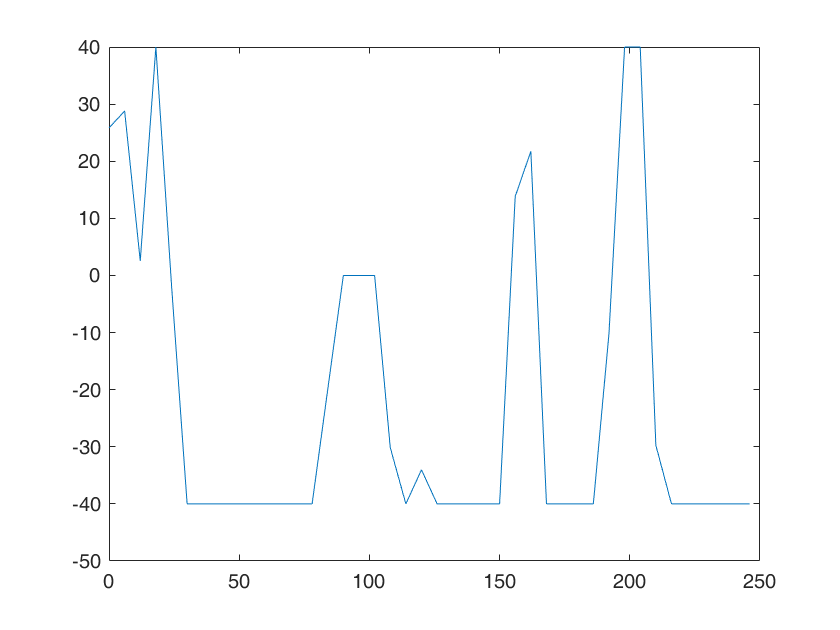

dyn0=load('xt_chgptFilterNotWorkingExample.mat');
t=dyn0.t;
x=dyn0.x;

frameInterval=6;
zeroSpeedThresh = 5;
switchTooCloseThresh = 4;


tFr = 0:frameInterval:max(t);
xFr = interp1(t,x,tFr);

dxFr= diff(xFr);
v=dxFr/frameInterval;

figure;plot(tFr(1:end-1),v)

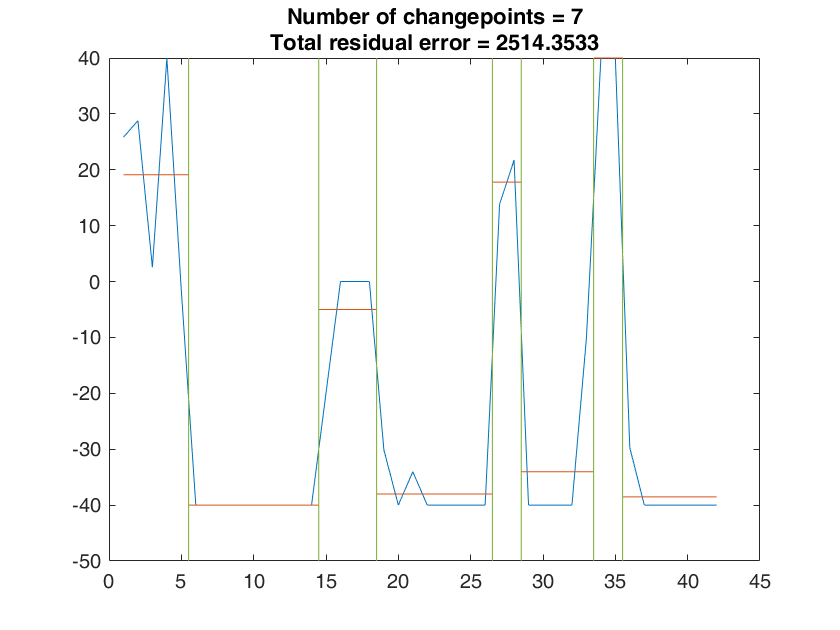

findchangepts(v,'MinThreshold',1000)

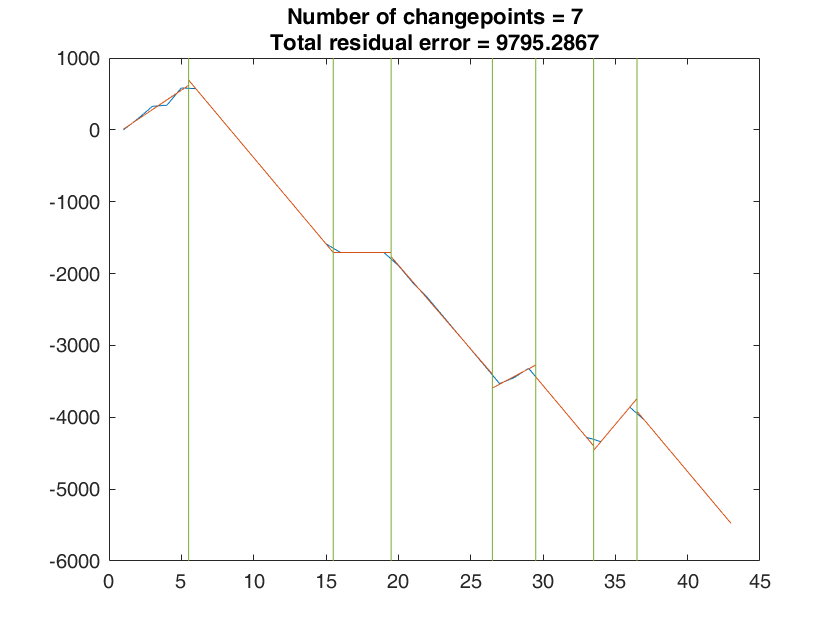

findchangepts(xFr,'Statistic','linear','MinThreshold',1000,'MinDistance',3)

above result looks pretty sensible and also quite similar to how analysis is performed by eye. Does it work for previously tested conditions or there going to need to be lots of parameter tuning

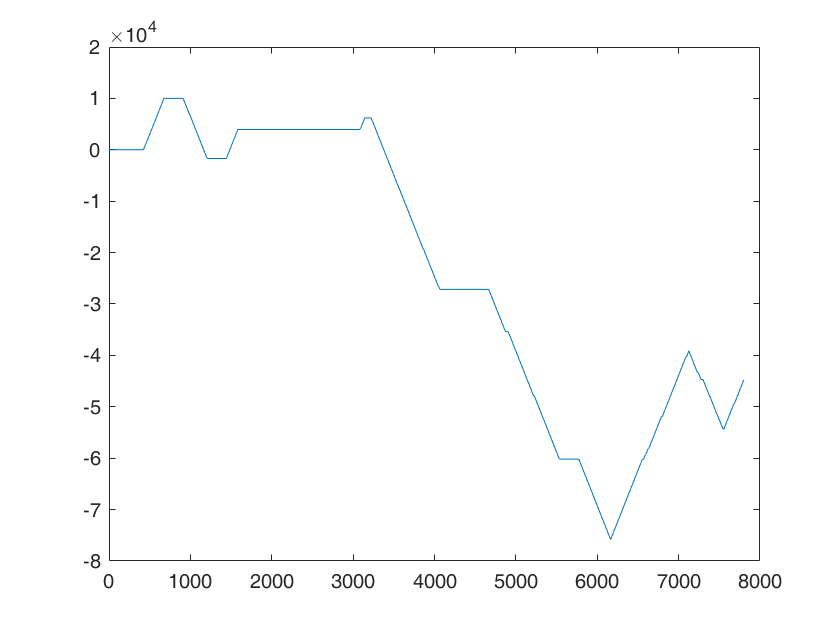

dyn1 = load('exemplarLipowskiDynamics1.mat');
t=dyn1.t;
x=dyn1.x;

plot(t,x);

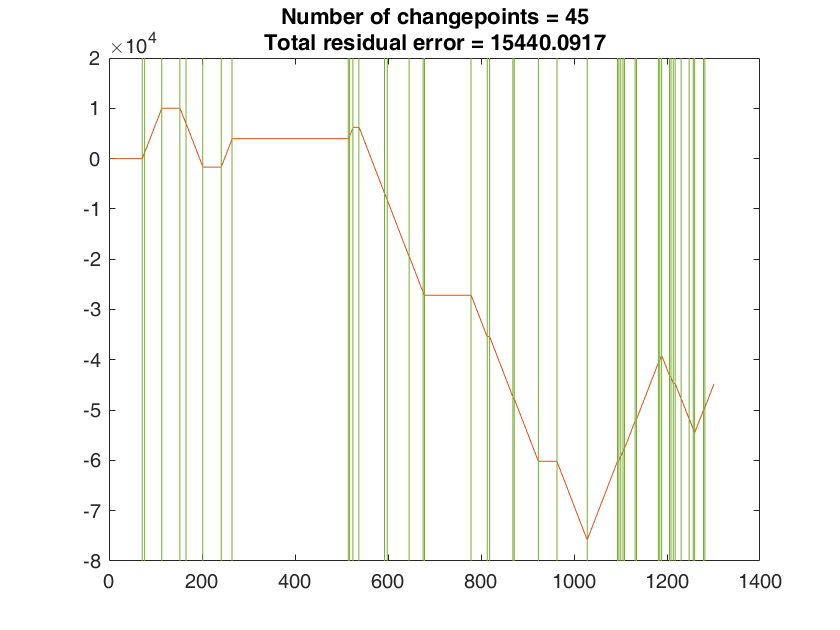

tFr = 0:frameInterval:max(t);
xFr = interp1(t,x,tFr);
findchangepts(xFr,'Statistic','linear','MinThreshold',1000,'MinDistance',3)

dxFr= diff(xFr);
v=dxFr/frameInterval;
figure;
plot(tFr(1:end-1),v);
%filter out near zero speed
vThresh=5

vThresh = 5

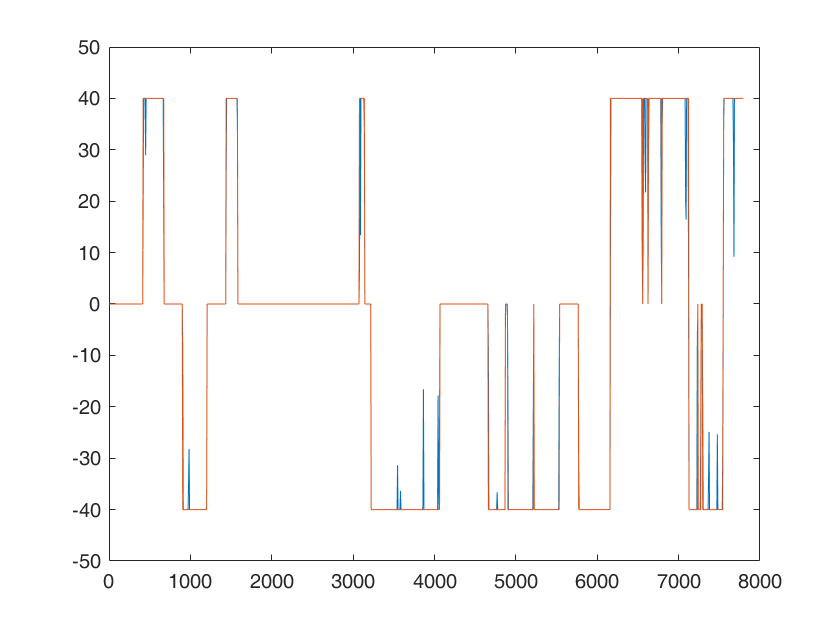

v2= v;
v2(abs(v2)<=vThresh)=0;
vSign = v2;
vSign(vSign>0) =1;
vSign(vSign<0) =-1;

hold all;
plot(tFr(1:end-1),vSign*40)

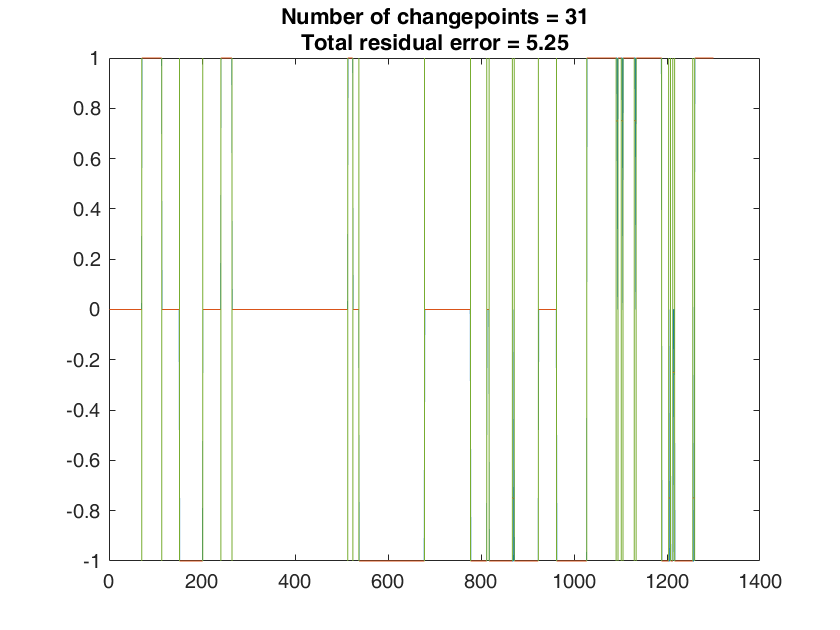

findchangepts(vSign,'MinThreshold',0,'MinDistance',4)

not really working

dyn0=load('xt_chgptFilterNotWorkingExample.mat');
t=dyn0.t;
x=dyn0.x;

frameInterval=6;
zeroSpeedThresh = 5;
switchTooCloseThresh = 4;


tFr = 0:frameInterval:max(t);
xFr = interp1(t,x,tFr);

dxFr= diff(xFr);
v=dxFr/frameInterval;
%filter out near zero speed
vThresh=5

vThresh = 5

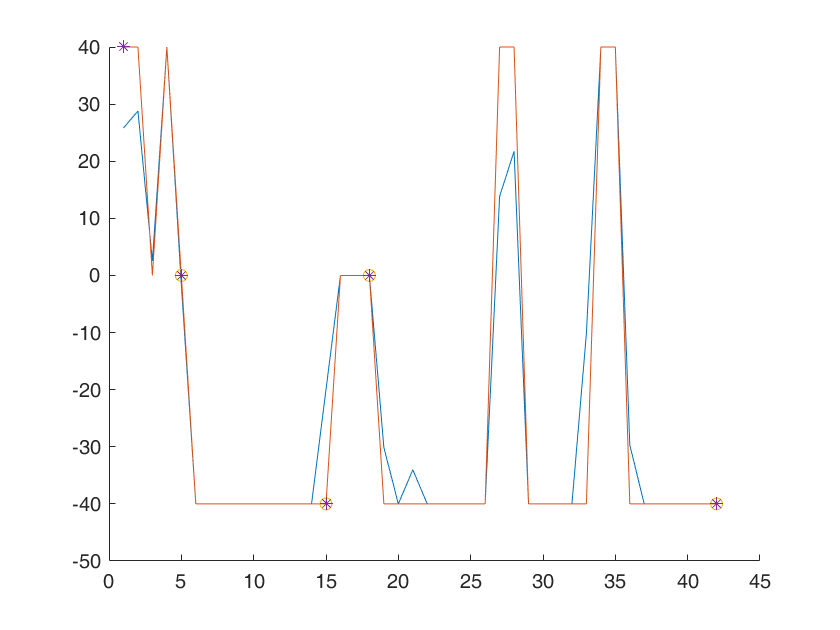

v2= v;
v2(abs(v2)<=vThresh)=0;

%todo:
%loop through and find sign changes or pauses
%need to identify states(beginning and end)
%measure type of state (motile, paused), length of state, average speed, and next state
%(motile paused)
%exclude states that are too close to last one
vSign = v2;
vSign(vSign>0) =1;
vSign(vSign<0) =-1;

figure;
hold all
plot(v);
plot(vSign*40);
chgpt=find(diff(vSign)~=0);
%add the first and last frames as states
chgpt=[1,chgpt,numel(tFr)-1];

tChgPt=tFr(chgpt);
%plot(tChgPt,vSign(chgpt),'x')
%Filter out short trajectories
frameThresh=3;
chgptFilt=chgpt;
ii = 2;
while ii <= numel(chgptFilt)
    if  ii > 1 && (chgptFilt(ii)-chgptFilt(ii-1))<frameThresh
        if vSign(chgptFilt(ii-1))==vSign(chgptFilt(ii)+1)%previous state same as current state
            %delete both chgptFilt
            chgptFilt(ii-1:ii)=[];
            ii=ii-1;
        else
            %dlete only previous chgptFilt
            chgptFilt(ii-1)=[];
        end
    else
        ii=ii+1;
    end
end
tChgPtFilt=tFr(chgptFilt);
plot(chgptFilt, vSign(chgptFilt)*40,'o')
%what if we add back in the first and last points if they are sufficiently
%far away from a change point
if chgptFilt(1)~=1 && chgptFilt(1)-1>=frameThresh
    chgptFilt=[1,chgptFilt];
end
if chgptFilt(end)~=numel(vSign) && (numel(vSign)-chgptFilt(end))>=frameThresh
    chgptFilt=[chgptFilt, numel(vSign)];
end
plot(chgptFilt, vSign(chgptFilt)*40,'*')

Ok update analyseSimDynamics.m to include this 

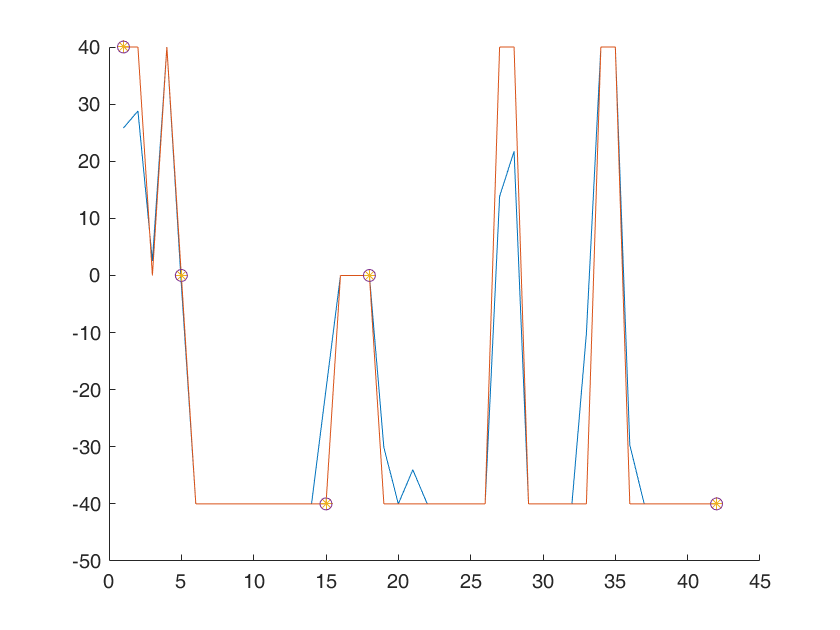

zeroSpeedThresh = vThresh;
switchTooCloseThresh = frameThresh;
[simResultAuto, chgptAuto, tFrAuto,xFrAuto] = analyseSimDynamics(t,x,frameInterval,zeroSpeedThresh, switchTooCloseThresh);
figure;hold all;
plot(v);
plot(vSign*40);
plot(chgptFilt, vSign(chgptFilt)*40,'*')
plot(chgptAuto, vSign(chgptAuto)*40,'o')

Try it on the other test case

t=dyn1.t;
x=dyn1.x;
tFr = 0:frameInterval:max(t);
xFr = interp1(t,x,tFr);
dxFr= diff(xFr);
v=dxFr/frameInterval;
figure
plot(t,x);

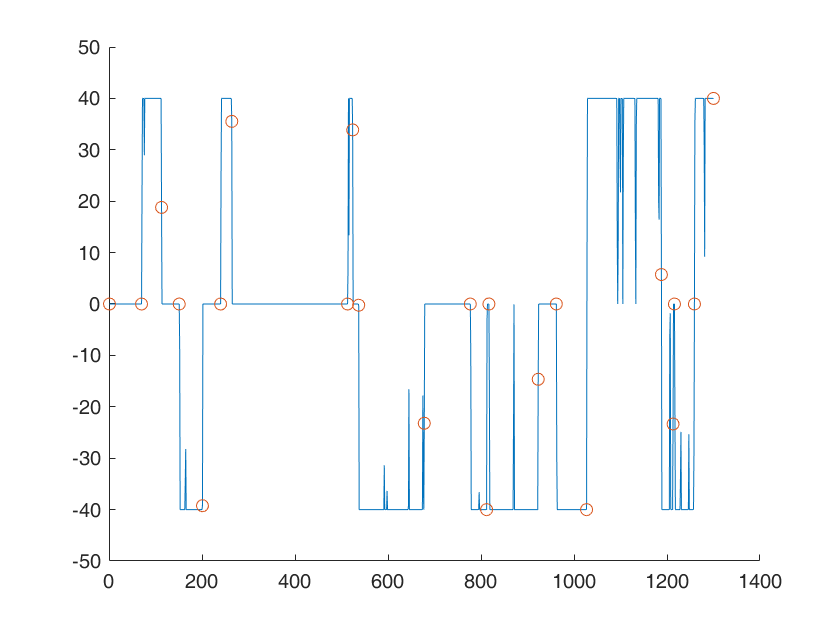


[simResultAuto, chgptAuto, tFrAuto,xFrAuto] = analyseSimDynamics(t,x,frameInterval,zeroSpeedThresh, switchTooCloseThresh);
figure;hold all;
plot(v);
plot(chgptAuto, v(chgptAuto),'o')

Seems to work ok now